## Matlab Code for COMP 558 -- lecture 3  (intro to filtering)

We'll start off with some examples of how convolution and cross-correlation work  in Matlab for the 1D examples.   Later we'll look at the 2D case.

We'll first define an edge:

N = 14;
Iedge = 0.2 * ones(1,N)

Iedge =     0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000    0.2000


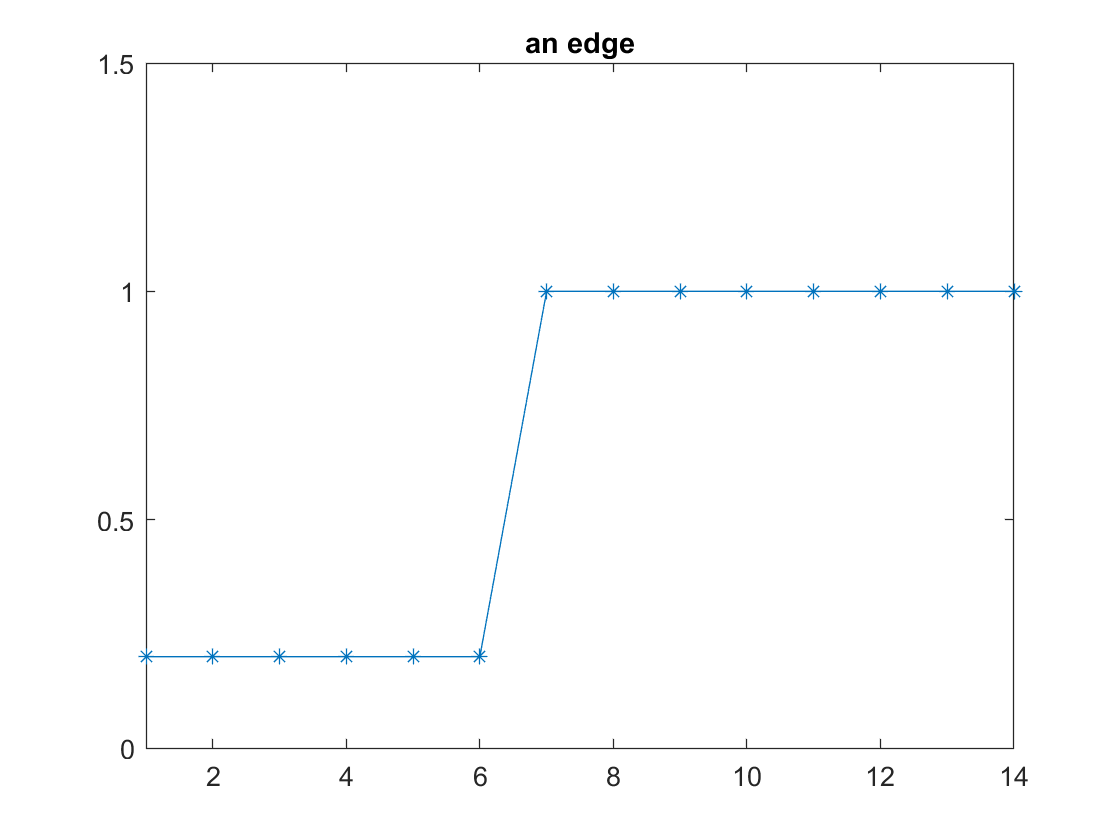

Iedge(N/2:end) = 1; 
plot(Iedge,'*-'); 
axis([1 N 0 1.5])
title('an edge')

Now define functions for taking the local difference and local average.

D = [1 0 -1]       % local difference

D =      1     0    -1


B = [.25 .5 .25]   % local average (blur)

B =     0.2500    0.5000    0.2500


#### **1D Convolution using Matlab conv**

Let's convolve Iedge with these functions and plot the results. 

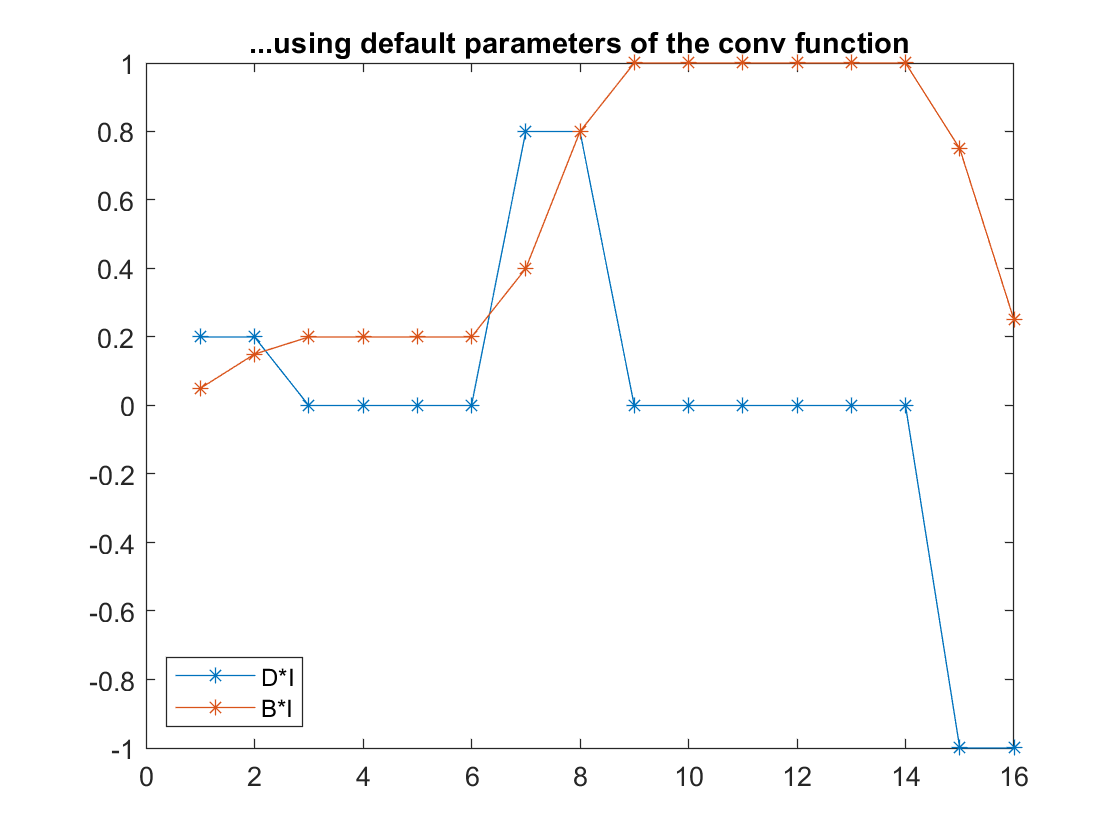

plot(conv(D,Iedge),'*-');  hold on;
plot(conv(B,Iedge),'*-');  
legend('D*I', 'B*I', 'Location', 'southwest')
title('conv ...using default parameters ')
hold off

There are a few things to note.  First,  although the image has N=14 data points, the result has 16 data points.  In general, when we convolve two vectors of length N1 and N2, we get a result of length N1+N2-1.   The reason is that  there are *at most* this many ways of positioning the two vectors relative to each other to get a non-zero value.   

The second thing to note is that the results look quite different on the left and right edge.  On the left edge, the result is 0.  This is because the Iedge vector has values 0 there, so no matter what filter "f" we use,  we will get 0.   But on the right edge,  the value that we get will be partial sums of the elements of the filter, weighted by values of I on the right edge.

One tries to avoid these boundary issues in a few different ways.  First, one might want to make the output have the same size as one of the input arguments.    This can be done by adding the parameter 'same'.  This parameter makes the output have the same size as the first argument, which is not what we want in our case.   

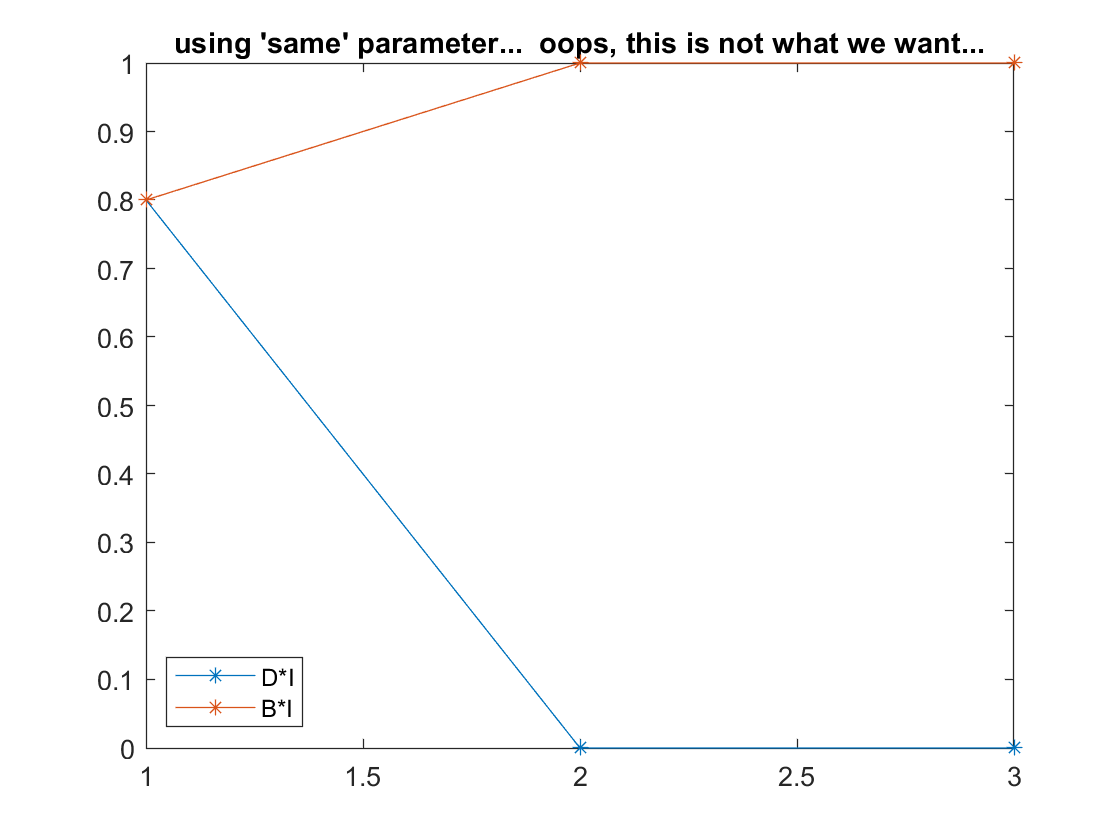

plot(conv(D,Iedge, 'same'),'*-');  hold on;
plot(conv(B,Iedge, 'same'),'*-' );  
legend('D*I', 'B*I', 'Location', 'southwest')
title('using ''same'' parameter...  oops, this is not what we want...')
hold off

If we swap the order of the arguments, then we will get a result of size N (the Iedge vector) which is more what we want in the present context of an edge and a filter.    

In particular, note that the Matlab function conv is not commutative -- unlike what I claimed in the lecture notes.

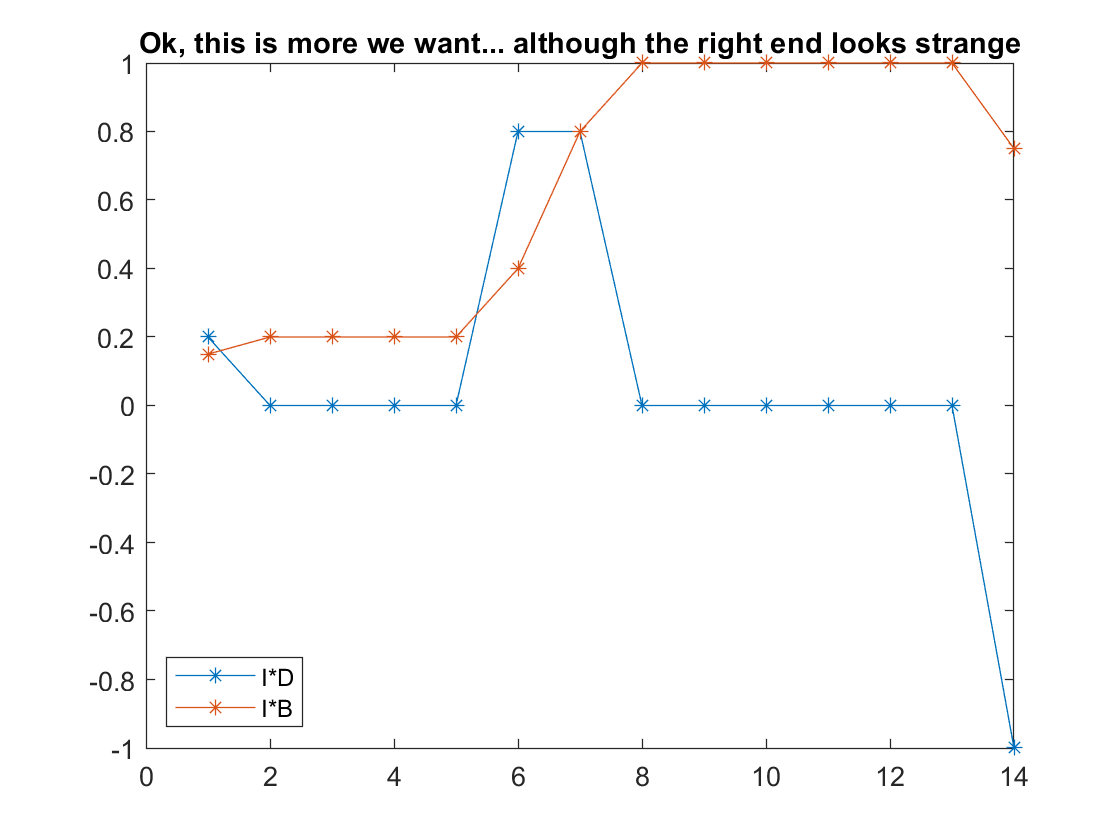

plot(conv(Iedge,D, 'same'),'*-');  hold on;
plot(conv(Iedge,B, 'same'),'*-' );  
legend('I*D', 'I*B', 'Location', 'southwest')
title('Ok, this is more we want... although the right end looks strange')
hold off

This still gives us artifacts on the right end.  We would have artifacts on the left end too, if the Iedge vector has non-zero values there.   

To avoid such artifacts, one can use the 'valid' parameter for the conv function.   The output will then shrink to size N1 - N2 + 1.   This is the number of ways that the second vector can be positioned *strictly inside* the first vector.

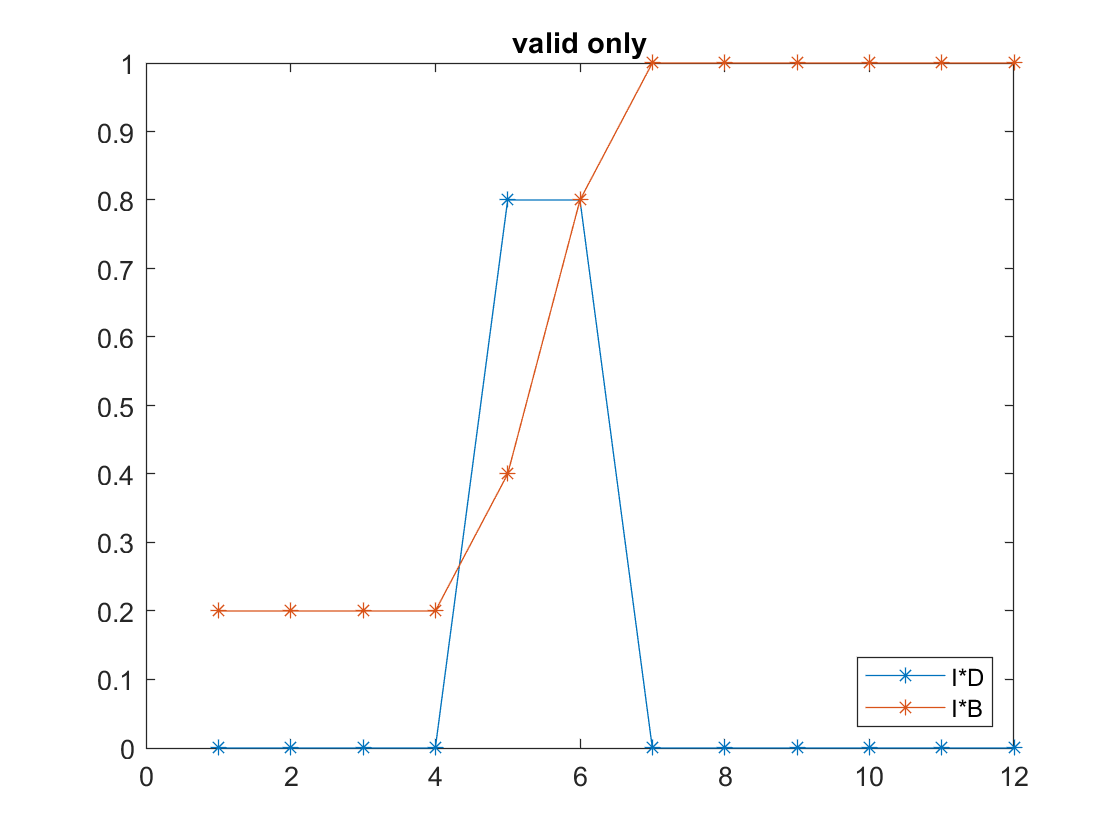

plot(conv(Iedge,D, 'valid'),'*-');  hold on;
plot(conv(Iedge,B, 'valid'),'*-' );  
title('valid only')
legend('I*D', 'I*B', 'Location', 'southeast')
hold off

Notice that the positions where the Iedge*D function takes it max value depend on the parameter that is used, since the number of samples changes.     If the relative positions of input and output points are important, then one needs to take care.

#### **1D cross-correlation using Matlab xcorr**

Let's use the Matlab function xcorr instead of conv.   As you can see, the length of the result is much large than above.   The reason is that xcorr appends 0's to the length of the smaller vector so that it has the same size as the larger vector, and it outputs a result of length 2*max(N1,N2) - 1 which corresponds to the number of ways of overlapping the two functions.    We will not be using "xcorr" further, and so I mention it here only for curiosity.

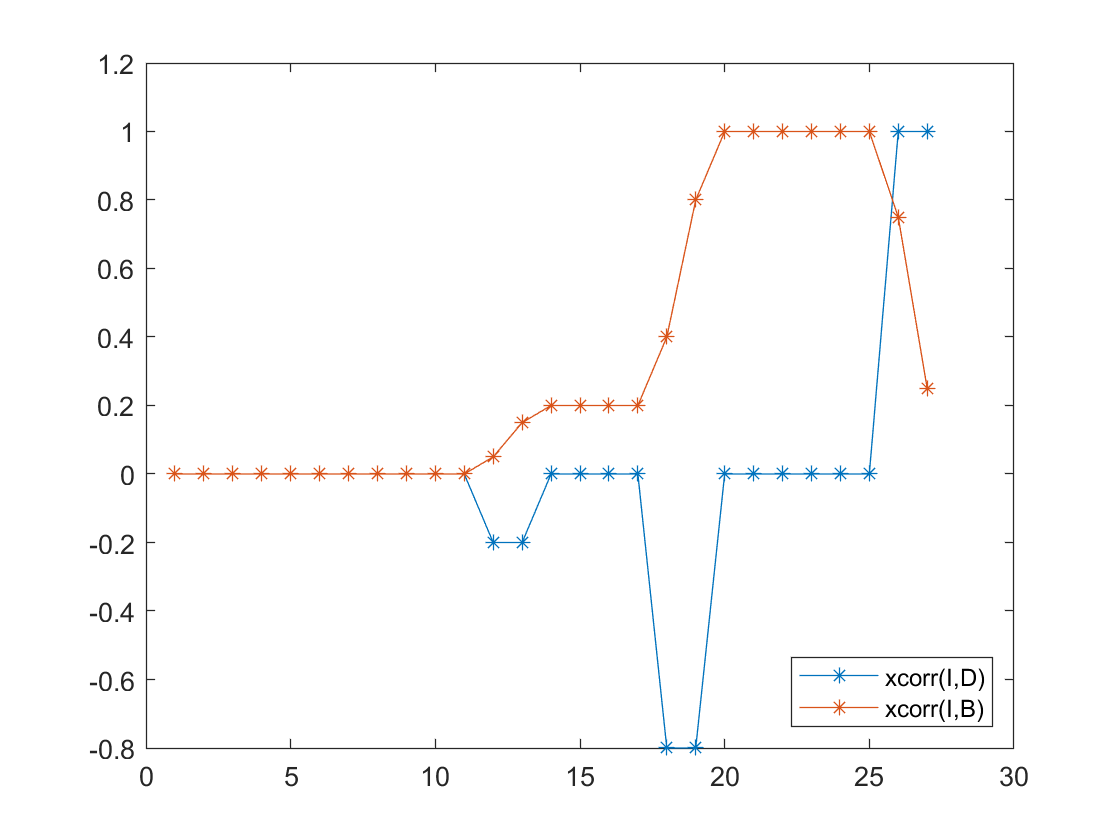

plot(xcorr(Iedge,D),'*-');  hold on;
plot(xcorr(Iedge,B),'*-' );  
legend('xcorr(I,D)', 'xcorr(I,B)', 'Location', 'southeast')
hold off

Let's now look at some 2D examples.    